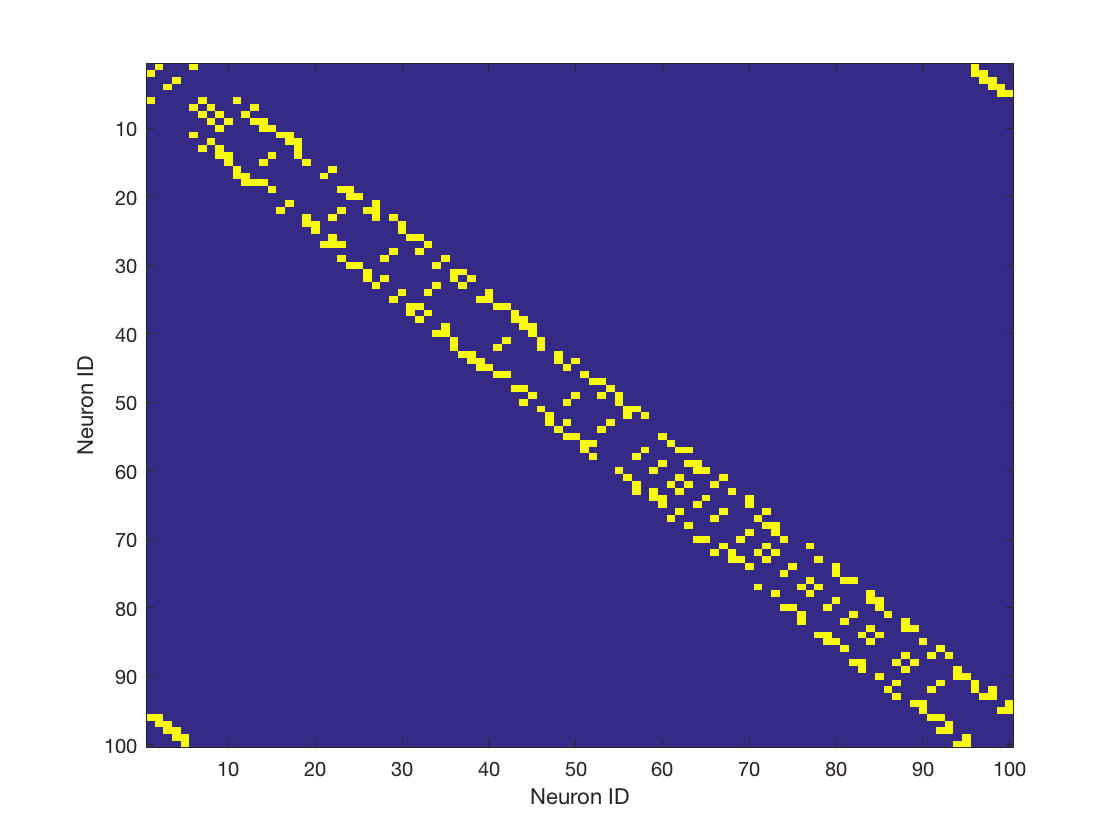

% Generate the tube adjacency matrix
close all
clear

% tube parameters
m=5;    % wideness
n=20;   % length

% connection probability, taken from Data (Chris RP2 dataset)
p=[0, 0.0714, 0.6429, 0.2857];

% max number of repeats to get the desired connectivity
trials=100;

A_tube=M_FullTube_prob_cut_add(n,m,p,trials);

figure
imagesc(A_tube);
xlabel('Neuron ID')
ylabel('Neuron ID')


save(sprintf('Adjacency_%dX%d',n,m),'A_tube');


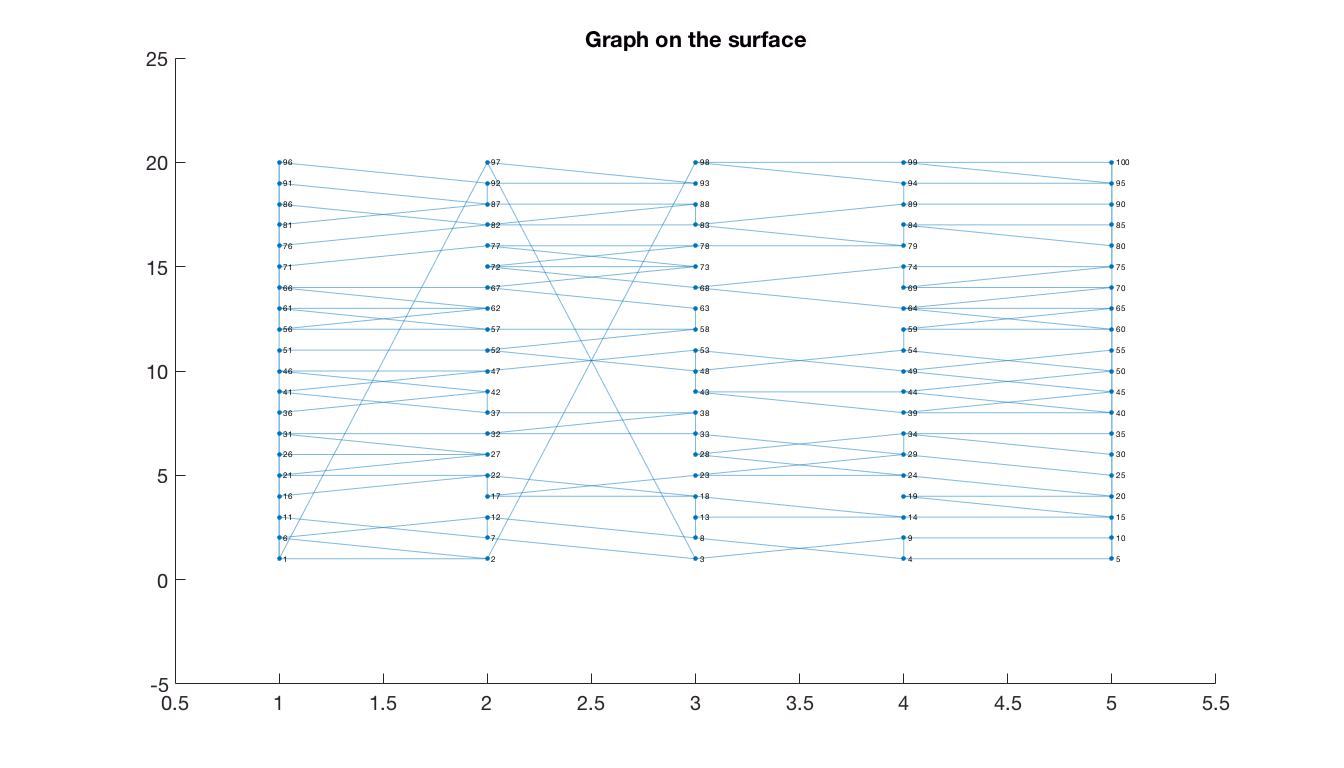

%% Plot the graph on the surface

% graph parameters

close all
figure('units','normalized','outerposition',[0 0 0.7 0.7]); % show figure window

A_graph=graph(A_tube);
% tube parameters
m=5;    % wideness
n=20;   % length

[Y,X]=meshgrid(1:n,1:m);        
x=reshape(X,[1,m*n]);
y=reshape(Y,[1,m*n]);
h=plot(A_graph,'Xdata',x,'Ydata',y);    %handle for the graph plot

box off

title('Graph on the surface')
set(gca,'Fontsize',20)

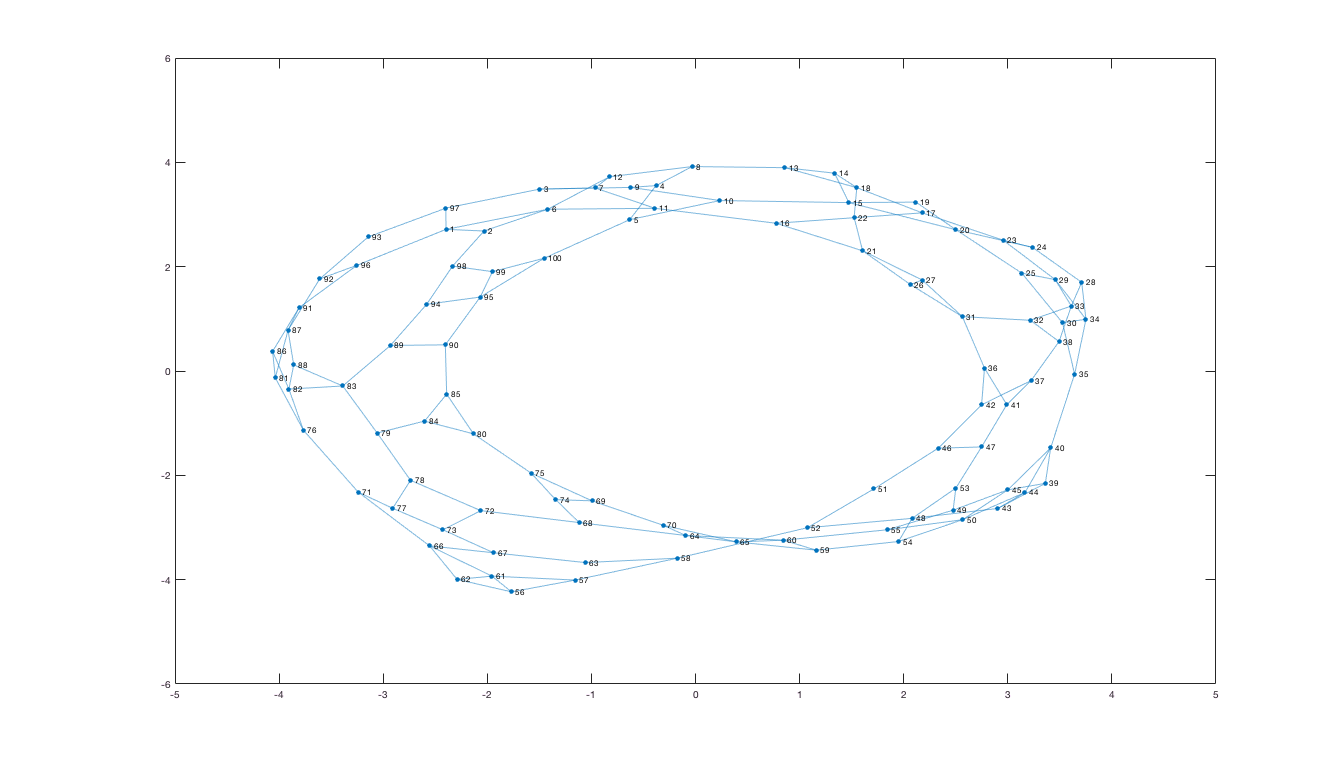

% Plot as graph object

A_biograph=graph(A_tube);

plot(A_biograph,'Layout','force');

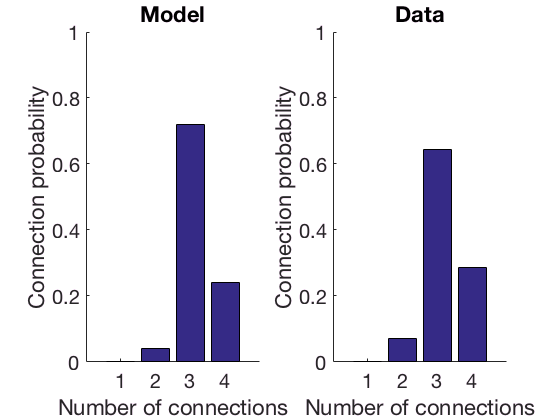

%% Plot the connection probability and compare with data
A=A_tube;

figure

A_sum=sum(A);              % take summ of all the elements

A_conn=[length(find(A_sum==1)),length(find(A_sum==2)),...
   length(find(A_sum==3)),length(find(A_sum==4)),...
   length(find(A_sum==5)), length(find(A_sum==6)),...
   length(find(A_sum==7)), length(find(A_sum==8)),...
   length(find(A_sum==9)),length(find(A_sum==10))];

% Connectivity distribution
A_conn=A_conn/length(A);
A_conn=A_conn(1:4);        % SHOWS ONLY UP TO 4 CONNECTIONS

subplot(1,2,1)
bar(A_conn);
ylabel('Connection probability');
xlabel('Number of connections');
ylim([0 1])
title('Model')
box off;
set(gca,'Fontsize',20);

subplot(1,2,2)
bar(p);
ylabel('Connection probability');
xlabel('Number of connections');
set(gca,'Fontsize',20);
title('Data');
ylim([0 1])
box off;